format shortG
rawfoldincs = readmatrix("rawfoldincs.txt");
rawfoldincs(:,15:end)=[]

rawfoldincs =             1            1            1            1            1            1            1            1            1            1            1            1            1            1
        1.078         1.53        1.358        1.548        1.052        1.052         0.94        0.718       1.0855         1.19        1.131       1.5582        1.952       1.1377
       6.1224       4.6158       4.2724       6.3406        5.555        5.555       6.1277       6.0724        4.147       5.0623       4.6189       3.9479       4.8302       4.2567
       5.4756       4.7525        3.882        3.027          4.5          4.5       3.2186       3.4439       4.1462       6.0479       4.0482       5.3647       6.5694       3.4422
          NaN       2.3012       1.6283       1.3062       2.5181       2.5181       3.6119       2.2886       3.4762       4.1757       2.3177       2.2001       2.0197       2.5865
          NaN          NaN       1.3772       1.2429          NaN      

logparams = readmatrix("alllogparams.txt");
logparams(10:end,:)=[]

logparams =     7.871e+07      0.96046
   4.9003e+07      0.98128
   2.5625e+07      0.86286
   2.2667e+07       1.0956
   4.0561e+07      0.94521
   5.2106e+07      0.85035
    7.496e+07      0.63905
   4.4712e+07       1.0164
   5.0838e+07       1.0025


initstate = [0.1,1];
actions = [0.18, 0.21, 0.24, 0.27, 0.3, 1];
day = [0,3,5,7,9,11];
culturenum = 14;
concentrationThreshold = 2.5;
rewards = zeros(numel(culturenum));
simresults = zeros(size(rawfoldincs,1),culturenum);
Reward1=1;
Penalty1=-2.5;

donoridx = ["t054","t046","t051","t062","t031","t031","t052","t038","t036","t036","t036","t066","t066","t066"]

donoridx = 1×14 string array
    "t054"    "t046"    "t051"    "t062"    "t031"    "t031"    "t052"    "t038"    "t036"    "t036"    "t036"    "t066"    "t066"    "t066"


donorlist = ["t054","t046","t051","t062","t031","t052","t038","t036","t066"]

donorlist = 1×9 string array
    "t054"    "t046"    "t051"    "t062"    "t031"    "t052"    "t038"    "t036"    "t066"


Action =           0.3


Action =           0.3


Action =      1


conforplot =           0.1            0
          0.1            0
       0.1078            3
       0.1078            3
         0.66            5
        0.198            5
       1.0842            7
      0.32525            7
          NaN            9
          NaN            9


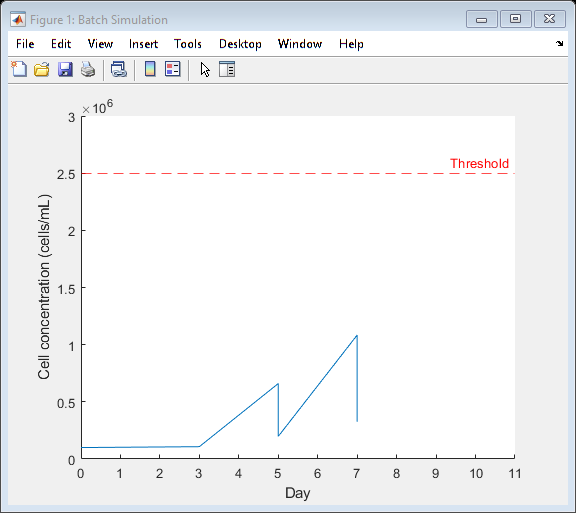

Action =           0.3


Action =           0.3


Action =      1


conforplot =           0.1            0
          0.1            0
        0.153            3
        0.153            3
      0.70622            5
      0.21187            5
       1.0069            7
      0.30207            7
      0.69513            9
      0.69513            9


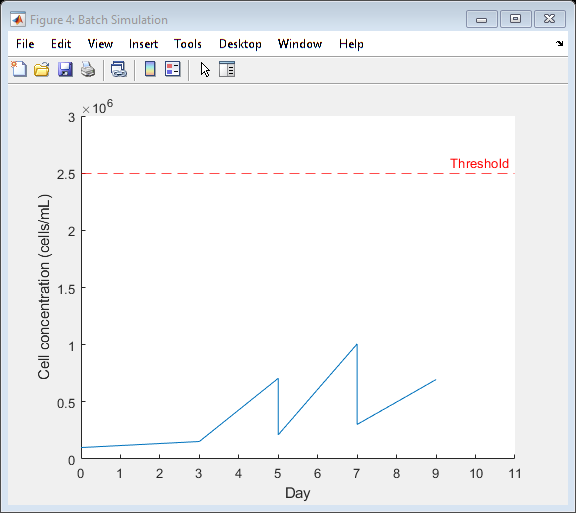

Action =           0.3


Action =           0.3


Action =      1


conforplot =           0.1            0
          0.1            0
       0.1358            3
       0.1358            3
      0.58019            5
      0.17406            5
      0.67569            7
      0.20271            7
      0.33007            9
      0.33007            9


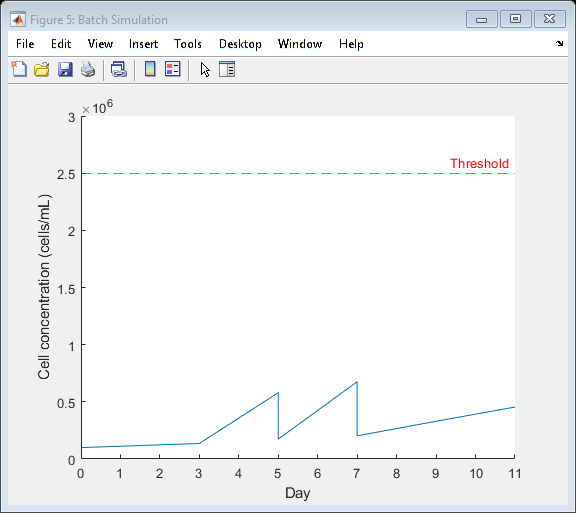

Action =           0.3


Action =           0.3


Action =      1


conforplot =           0.1            0
          0.1            0
       0.1548            3
       0.1548            3
      0.98152            5
      0.29446            5
      0.89132            7
       0.2674            7
      0.34926            9
      0.34926            9


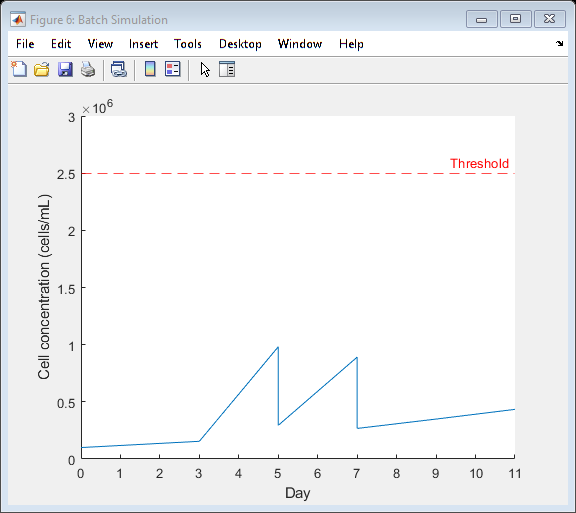

Action =           0.3


Action =           0.3


Action =      1


conforplot =           0.1            0
          0.1            0
       0.1052            3
       0.1052            3
      0.58439            5
      0.17532            5
      0.78893            7
      0.23668            7
      0.59597            9
      0.59597            9


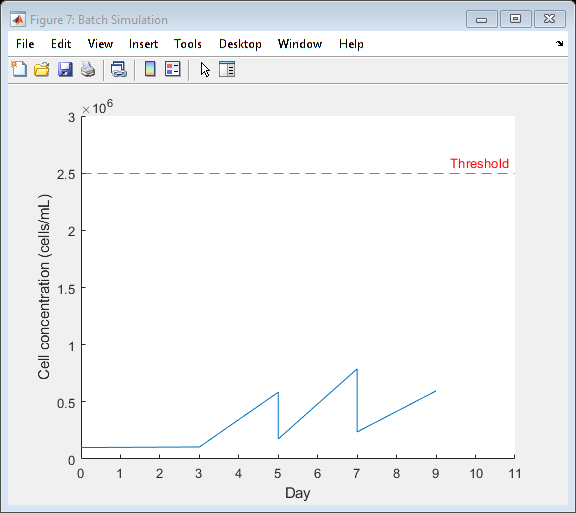

Action =           0.3


Action =           0.3


Action =      1


conforplot =           0.1            0
          0.1            0
       0.1052            3
       0.1052            3
      0.58439            5
      0.17532            5
      0.78893            7
      0.23668            7
      0.59597            9
      0.59597            9


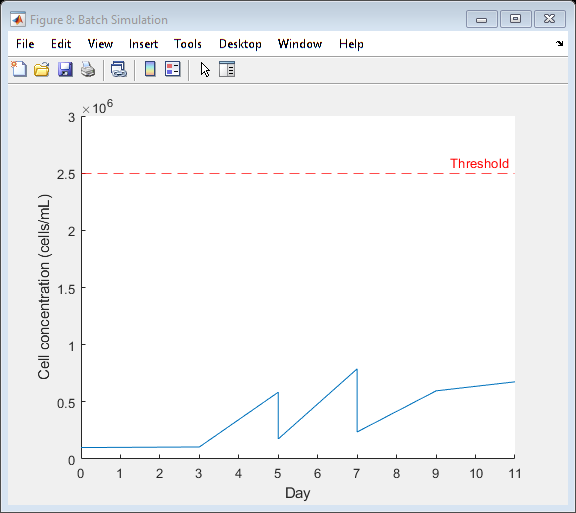

Action =           0.3


Action =      1


Action =           0.3


conforplot =           0.1            0
          0.1            0
        0.094            3
        0.094            3
        0.576            5
       0.1728            5
      0.55618            7
      0.55618            7
       2.0089            9
      0.60266            9


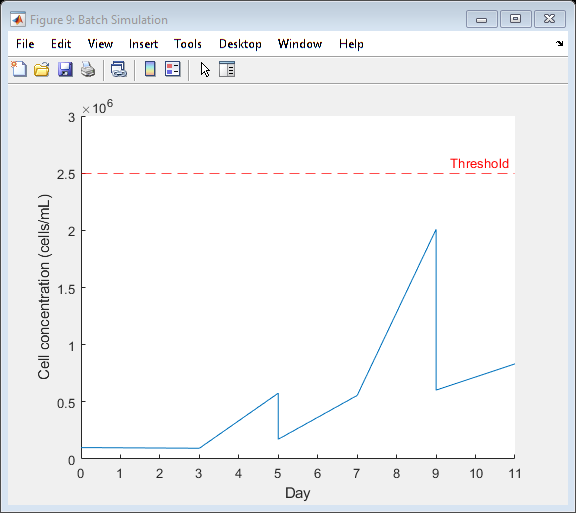

Action =      1


Action =           0.3


Action =           0.3


conforplot =           0.1            0
          0.1            0
       0.0718            3
       0.0718            3
        0.436            5
        0.436            5
       1.5015            7
      0.45046            7
       1.0309            9
      0.30928            9


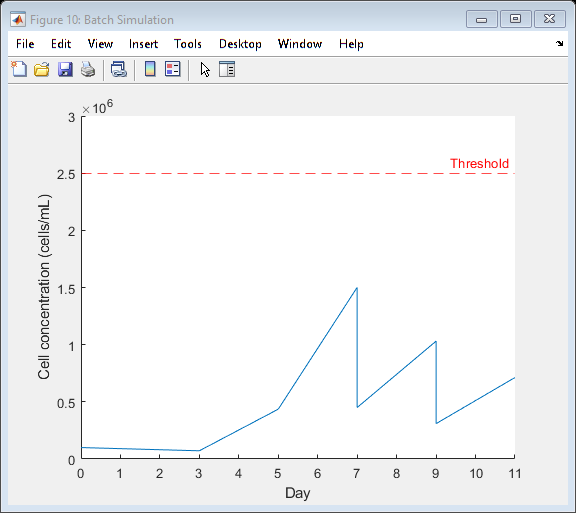

Action =           0.3


Action =      1


Action =           0.3


conforplot =           0.1            0
          0.1            0
      0.10855            3
      0.10855            3
      0.45014            5
      0.13504            5
      0.55991            7
      0.55991            7
       1.9463            9
       0.5839            9


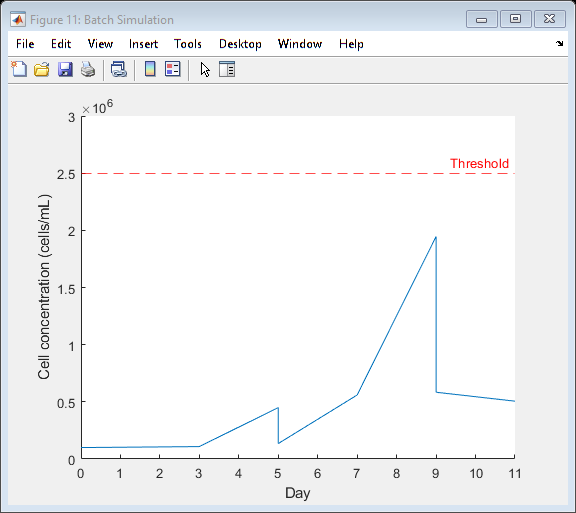

Action =           0.3


Action =           0.3


Action =      1


conforplot =           0.1            0
          0.1            0
        0.119            3
        0.119            3
      0.60241            5
      0.18072            5
        1.093            7
       0.3279            7
       1.3692            9
       1.3692            9


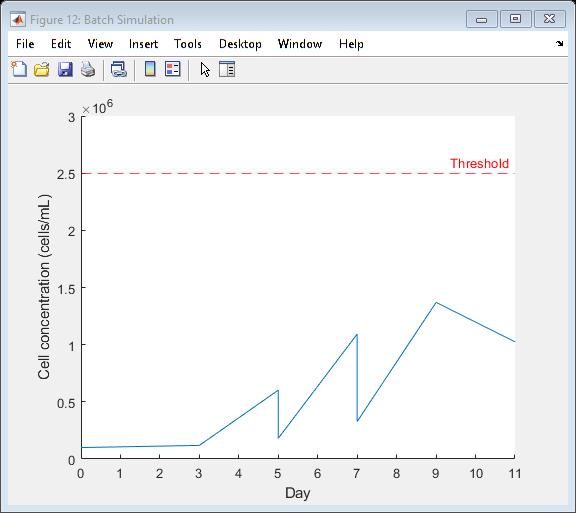

Action =           0.3


Action =           0.3


Action =      1


conforplot =           0.1            0
          0.1            0
       0.1131            3
       0.1131            3
      0.52239            5
      0.15672            5
      0.63441            7
      0.19032            7
      0.44112            9
      0.44112            9


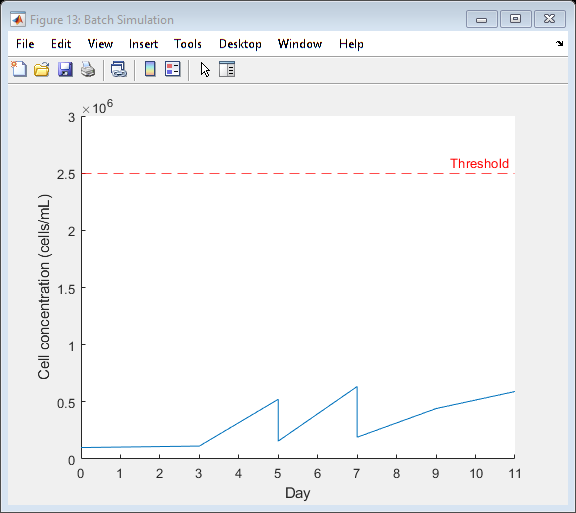

Action =           0.3


Action =           0.3


Action =      1


conforplot =           0.1            0
          0.1            0
      0.15582            3
      0.15582            3
      0.61515            5
      0.18455            5
      0.99003            7
      0.29701            7
      0.65344            9
      0.65344            9


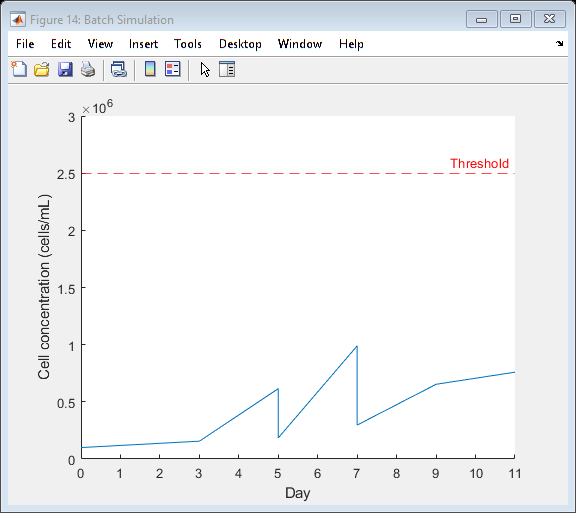

Action =           0.3


Action =          0.27


Action =      1


conforplot =           0.1            0
          0.1            0
       0.1952            3
       0.1952            3
      0.94286            5
      0.28286            5
       1.8582            7
      0.50171            7
       1.0133            9
       1.0133            9


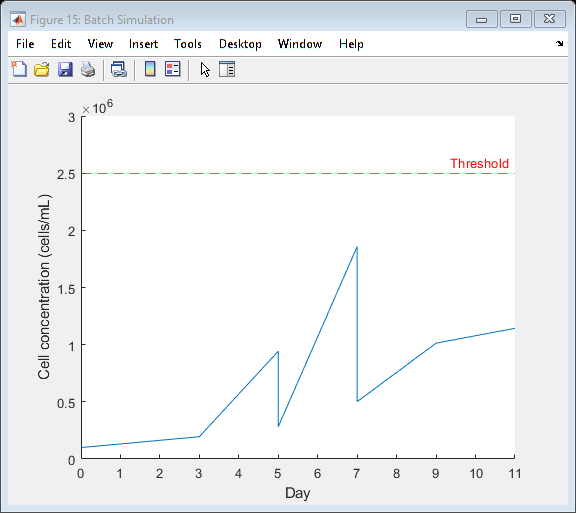

Action =           0.3


Action =      1


Action =      1


conforplot =           0.1            0
          0.1            0
      0.11377            3
      0.11377            3
      0.48429            5
      0.14529            5
      0.50011            7
      0.50011            7
       1.2935            9
       1.2935            9


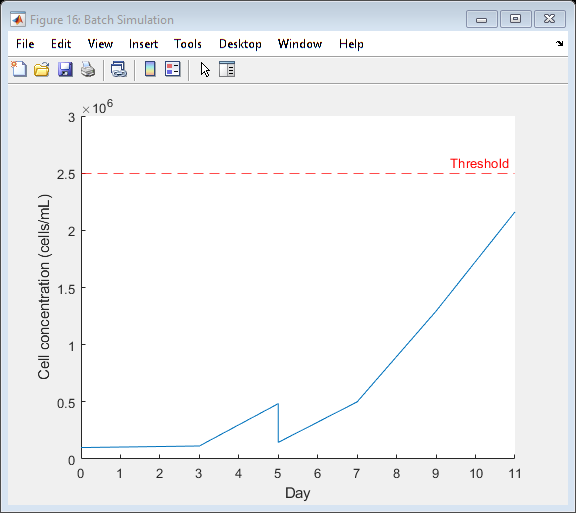

for i=1:culturenum
    State=initstate;
    timeStep=0;
    timsStepStart=0;
    Reward=0;
    foldExMap = rawfoldincs(:,i);
    simresult = zeros(size(rawfoldincs,1),1);
    conforplot = [];
    for j=1:numel(day)
        simresult(j) = State(1);
        if day(j)==0 | day(j)==11 | day(j)==3
            Action=1;
        else
            Action=getaction1(logparams(find(donorlist==donoridx(i)),:),initstate(1)*1000000,actions,concentrationThreshold,day(j),State(1))
        end
        if j==6
            conforplot = [conforplot; State]; 
        else
            [State,reward,conforplot]=step(State,Action,concentrationThreshold,foldExMap,Reward1,Penalty1,conforplot);
        end
        if isfinite(reward)
            Reward = Reward + reward;
        end
    end
    
    for k=1:size(conforplot,1)
        conforplot(k,2)=day(conforplot(k,2));
    end
    conforplot
    rewards(i)=Reward;
    simresults(:,i) = simresult; 

    Figure = figure('Name','Batch Simulation','Visible','on','HandleVisibility','off');
    ha = gca(Figure);
    ha.XLimMode = 'manual';
    ha.YLimMode = 'manual';
    ha.XLim = [0,11];
    ha.YLim = [0,3000000];
    xlabel(ha,'Day')
    ylabel(ha,'Cell concentration (cells/mL)')
    ha.TitleHorizontalAlignment = 'right';
    clf;
    hold(ha,'on');
    yline(ha,2500000,'r--','Threshold')      
    ConcentrationPlot = plot(ha,conforplot(:,2),conforplot(:,1).*1000000,'LineStyle','-','Color',[0, 0.4470, 0.7410]);
end


rewards

rewards =      -0.64803      -2.4388      -2.3691      -1.7549      -2.9255      -1.5753      -2.6014       -3.034      -3.4235      0.23225      -2.1085      -1.0669       1.2958       4.2148


simresults

simresults =           0.1          0.1          0.1          0.1          0.1          0.1          0.1          0.1          0.1          0.1          0.1          0.1          0.1          0.1
       0.1078        0.153       0.1358       0.1548       0.1052       0.1052        0.094       0.0718      0.10855        0.119       0.1131      0.15582       0.1952      0.11377
         0.66      0.70622      0.58019      0.98152      0.58439      0.58439        0.576        0.436      0.45014      0.60241      0.52239      0.61515      0.94286      0.48429
       1.0842       1.0069      0.67569      0.89132      0.78893      0.78893      0.55618       1.5015      0.55991        1.093      0.63441      0.99003       1.8582      0.50011
          NaN      0.69513      0.33007      0.34926      0.59597      0.59597       2.0089       1.0309       1.9463       1.3692      0.44112      0.65344       1.0133       1.2935
          NaN          NaN      0.45457       0.4341          NaN      0

totalscorelogistic = sum(rewards)

totalscorelogistic =       -18.203


function [State,reward,conforplot] = step(State,Action,concentrationThreshold,foldExMap,Reward1,Penalty1,conforplot)
    
    % Unpack state vector
    state = State;
    con = state(1);
    time = state(2);
    
    conforplot = [conforplot; [con,time]];

    % Apply system dynamics        
    con = con.*Action;
        
    conforplot = [conforplot; [con,time]];

    % calculate next state values
    time = time + 1;
    con = con * foldExMap(time);
    
    if con>(concentrationThreshold)
        overthreshold = true;
    else 
        overthreshold = false;
    end
    
    % Update system states
    State = [con,time];

    % Get reward    
    if overthreshold == false
        reward = con*Reward1;
    else
        reward = 5*concentrationThreshold-4*con*Reward1;
    end
    
    if Action<1
        reward = reward + Penalty1;
    end           
end

function Action = getaction1(logparam,initcon,actions,concentrationThreshold,day,statecon)
    for a=1:numel(actions)
        Action = actions(a);
        con = statecon;
        con1 = LGE(logparam, day, initcon);
        con2 = LGE(logparam, day+2, initcon);
        inc = con2./con1;
        con = con*Action;
        conpred = con*inc;
        if conpred>=concentrationThreshold
            if a==1
                break
            else
                Action = actions(a-1);
                break
            end
        end
    end
end